xlswrite("Game.csv",Game)
G1=Game(:,1).UBSFY;
G2=Game(:,2).EA;
G3=Game(:,3).TTWO;

figure(1);
plot(G1);
hold on;
plot(log(G1));
hold off;

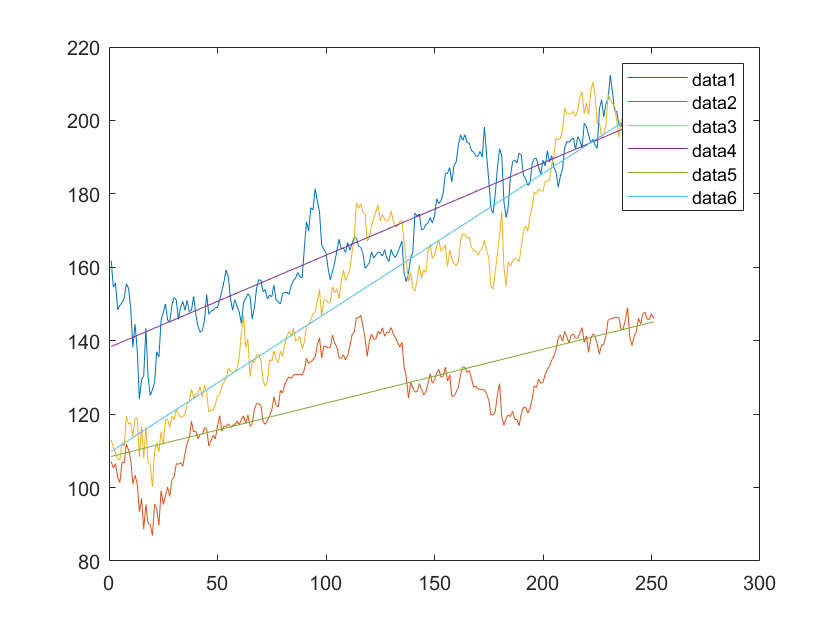

figure(2);
X = 1:1:251;
p1 = polyfit(X',10*G1,1);
p2 = polyfit(X',G2,1);
p3 = polyfit(X',G3,1);
plot(10*G1);
hold on;
plot(G2);
plot(G3);
plot(X',polyval(p1,X'));
plot(X',polyval(p2,X'));
plot(X',polyval(p3,X'));
hold off;

legend('show')